# An introduction to Image Stacks

An image stack is exactly what it sounds like: a stack of images. Think deck of cards or a sheaf of paper. Whereas a single image is—for all intents and puporses—infinitely thin, a  stack has volume and multiple slices

# Visualization

### Prism - image stack illustration

It helps to visualize an Image stack as a Prism - or a 3D cube, like this:

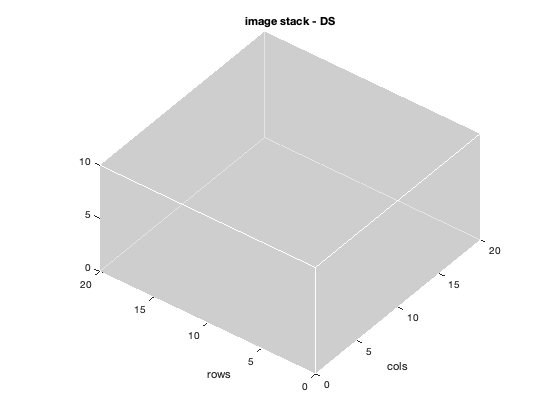

## Plane illustration

An image stack is exactly that: a stack of images. Think of an image stack as a stack of images piled on top of each other. The first dimension still represents the rows, the second represents the columns, while the third dimensions represent the slices (or planes) of the stack. This is similar to RGB images, but in this case, instead of channels, each plane represent depth (or in some instances, time). And you can have more than three planes. 

To indexing a plane, you simply place a value in the third position, as follows:

 - this would return all rows and all columns in the 5th plane as follows

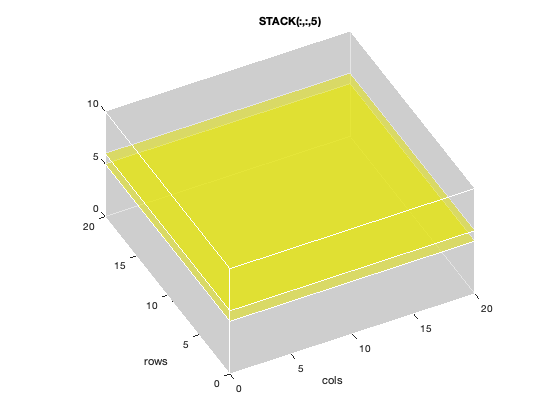

## Indexing an orthogonal plane of data

You can index planes parallel to the z-plane as follows:

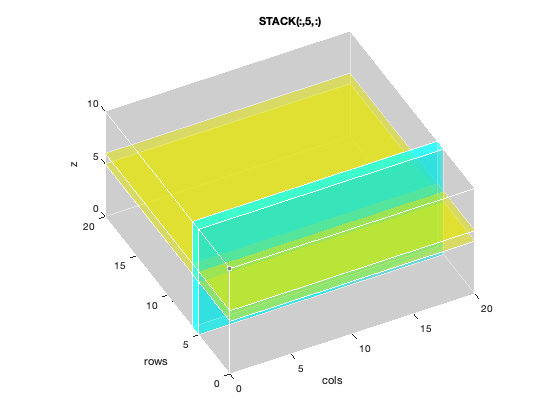

## Calculating the Max of a Stack across the 3rd dimension

Converting a 3D stack into a 2D stack is called a projection. One simple way to create a projection is run the **max **function across the 3rd dimension as follows:

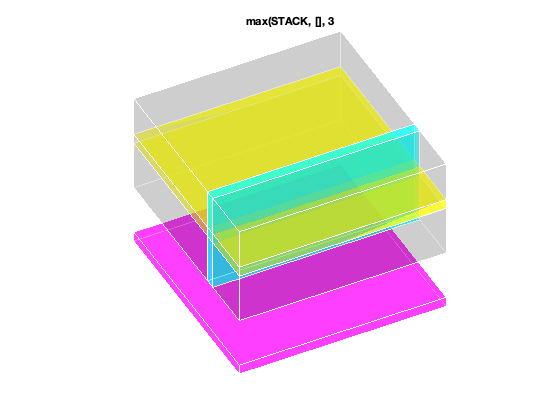

- The result is a 2D image (the magenta plane) that has the same x and y of the stack (but now has a z of 1). this has a max value from every column above that magenta plane

## Animation

Now enjoying an animation of indexing across all 10 planes of the prism

slice_animation; % this is a local function added to the bottom of the live script

# Bat File

Remember the volume from Fiji? Let's open that in MATLAB

## Get the file path

First, we need to tell MATLAB where the bat file is located (it's in the MATLAB Drive) and it's called 'bat-cochlea-volume.tif'

clearvars
clc
close all

Choose the file

bat_file = imgetfile;

## Read in the metadata

Before we can read in the stack, we need to explore the metadata

meta = imfinfo(bat_file);

- The metadata has 114 elements

- This means that there are 114 slices in the image

To inspect the metadata for one of the slices, we need to inspect one of the elements in the structure.

meta(1).Width
meta(1).Height
meta(1).BitDepth

- So the Volume is 154X121X114...

- And its an 8-bit stack

### Read in the volume

Great, lets read in our volume. We'll use the **imread** function:

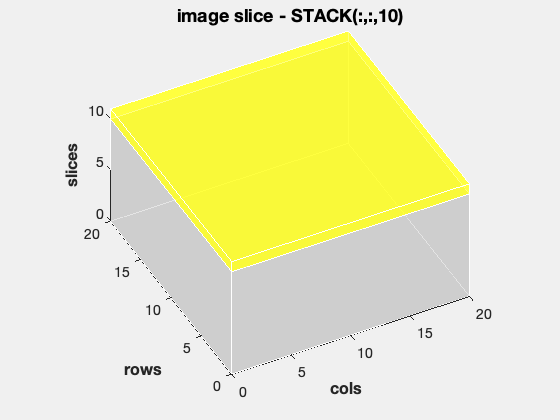

img = imread(bat_file);

imshow(img)

- And... this is not a 3D volume: its 2D.

- We appear to have only one slice

What happens if we add a second input to **imread**?

img = imread(bat_file,2);
imshow(img)

- Ah, that's the second slice. 

- So, the default for reading an image stack is to read in the first slice, unless otherwise indicated by the second input into **imread**

## Read in the volume, take two

So, to read in an entire image stack from a TIF file, we need to use a **FOR LOOP, **to read the stack slice by slice. For this volume, we will need to run the FOR LOOP 114 times or the number of slices in the stack. This also happens to be the number of elements in the metadata structure, *meta*. Also, notice that since we are using a FOR LOOP to create a variable, then we are going to need to preallocate. This is really important for volumes. Luckily, we have all the information that we need in the metadata.

IMG = zeros(meta(1).Height, meta(1).Width, numel(meta),'uint8'); % preallocate the variable as an 8-bit array with all zeros

for n=1:numel(meta)
    IMG(:,:,n) = imread(bat_file, n); % read slice by slice
end

- You should now have a 154X121X114 array in the workspace called IMG

## Indexing

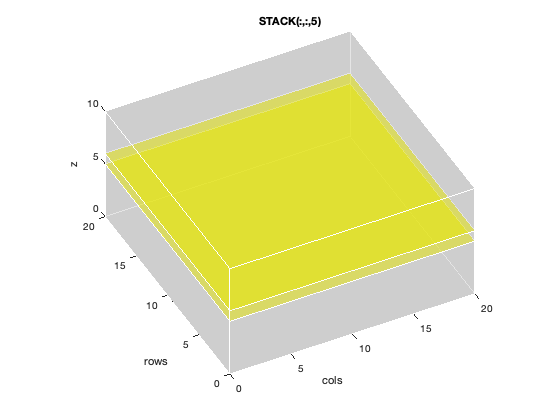

Indexing out slices is exactly like indexing out channels from an RGB image. You index the third dimension as follows:

slice = IMG(:,:,75);
imshow(slice)

- this returns the 75th slice in the stack

How would you index the 100th slice? And display?

Enter the syntax here:

slice = IMG(:,:,100);

ans = 121

imshow(slice)

ans = 154

## Montage

You can also quickly inspect every single slice in the stack using the function **montage**

montage(IMG)

ans = 8

## Explore the dataset

Use the Volume Viewer app to visualize the volume. 

volumeViewer(IMG)

- On the left side, you have the slice browsers. Move the scroll bars to scrub through the slices 

- In the center, there is a 3D rendering of the volume

- Change the rendering to Slice Planes

- Change the rendering to surface rendering

## Max Projection: From 3D to 2D

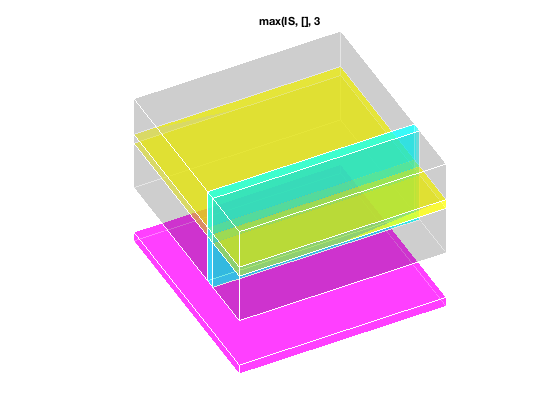

Sometimes, it is easier to explore a volume as a 2D image. This is a called a projection. In the above image, the max projection is the pink plane. Think of a projection as a flattened volume

You can easily generate a max projection of the model using the **max** function across the 3rd dimension, as follows

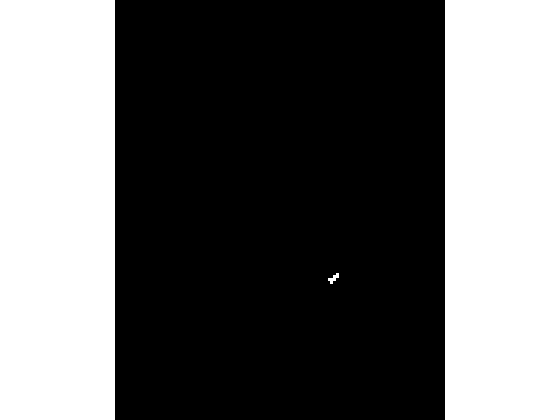

max_proj = max(IMG, [],3);

imshow(max_proj)

- This is like an aerial view of the volume, when the depth is collapsed down into one layer

## Stacks vs RGB

In MATLAB, the only real difference between a grayscale stack and an RGB image is the number of slices. As you recall, an RGB image has three and only three slices.

For example, we can show three slices of IMG as an RGB image

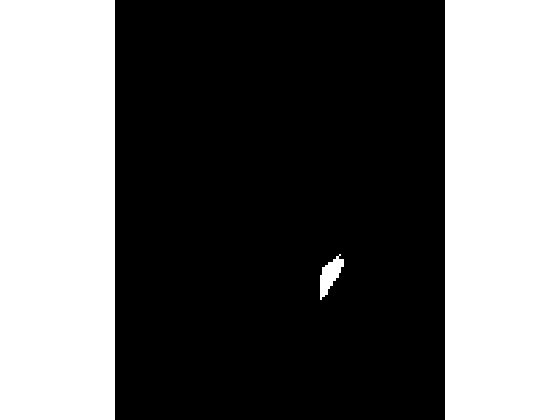

figure;
imshow(IMG(:,:,100:102)); title("RGB");

And here are those three slices separately.

figure;
tiledlayout(1,3,"TileSpacing","compact")

nexttile; imshow(IMG(:,:,100)); title('Slice 1')
nexttile; imshow(IMG(:,:,101)); title('Slice 2')
nexttile; imshow(IMG(:,:,102)); title('Slice 3')

- There is no real reason to do this, but we can do it. 

Or the 50th through 52nd slice

figure; imshow(IMG(:,:,50:52))

- It just has to be three slices to work

What happens if you input the whole stack into **imshow? **

- Or just two slices:

- Try it now 

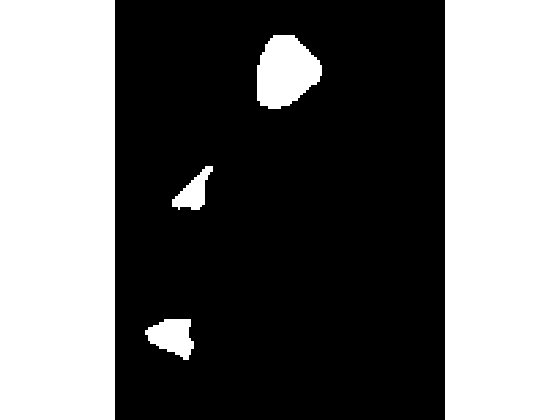

It fails. The function **imshow** can only handle grayscale or RGB images. It cannot display other types of information. So, it is up to you to keep track of what type of image you have loaded into the variable. You need to know what kind of data you are dealing with.

### Segmentation

The function **volshow** is the 3D equivalent to **imshow: **it is a simpler way to display 3D volumes.

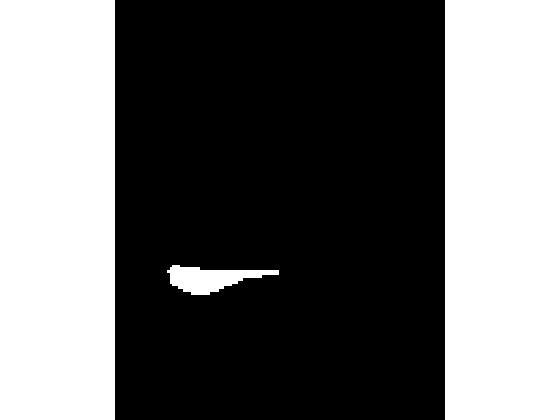

STACK = logical(IMG);
h = volshow(STACK) % like imshow, but for volumes

## Region properties

The function **regionprops3 **calculates properties for connected components  in 3D volumes. Notice that instead of area, you get volume.

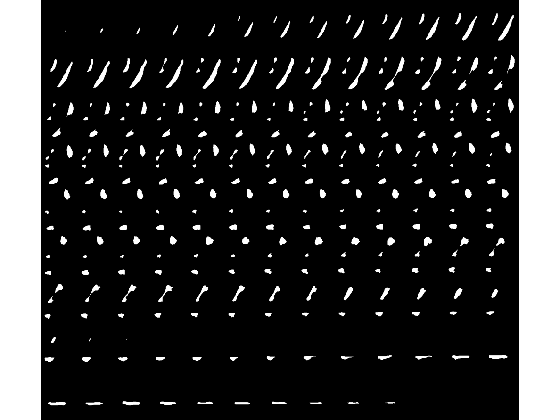

RP = regionprops3(STACK)

# EXAMPLE

Real-world data

## 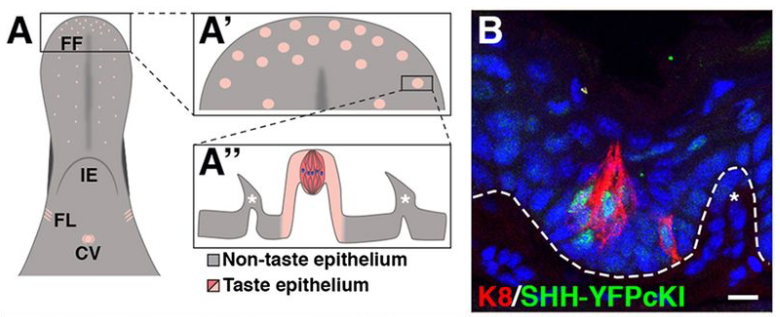

The datasets in this example were captured using a confocal microscope of tastebuds isolate from mouse tongues. [Castillo et al, Development, 2014](http://dev.biologists.org/content/141/15/2993#sec-13)

## Get Image File Paths

I have stored two TIF stacks in the data folder. When prompted, select **BOTH** of the following files:

- taste_bud_red.tif

- taste_bud_blue.tif

If you don't select two files, you will be prompted to do so (just re-run the code block).

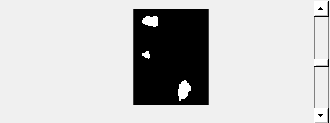

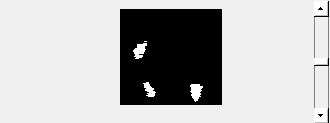

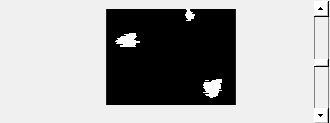

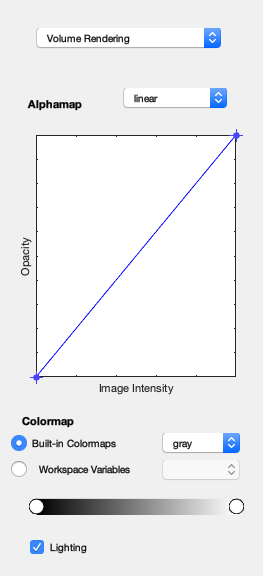

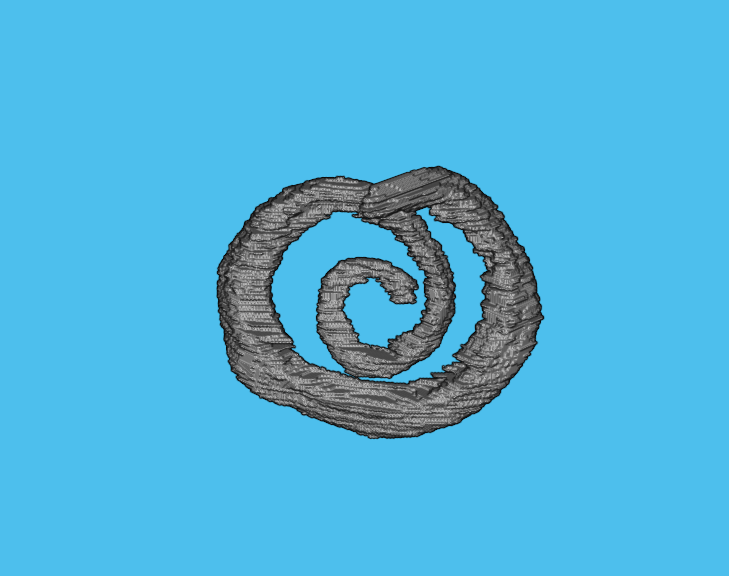

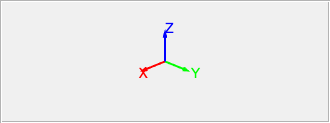

clearvars;

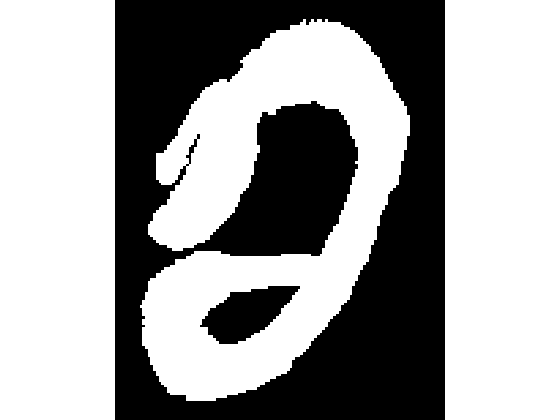

clc
im_files = imgetfile('Multiselect', true); % returns a cell array where each element contains the file path to one of the files you selected

if numel(im_files) ~= 2
    beep
    disp('Select TWO and only TWO files. Run this code block again')
else
    red_la = contains(im_files, '_red.tif') % find the red path

    path_red = im_files{red_la} % index out the red file path and assign to path_red
    path_blue = im_files{~red_la} % index out the red file path and assign to path_red
end

- Notice that we added an input to **imgetfile**, turning on the Multiselect feature

- When you select multiple files in **imgetfile**, you get back a cell array containing the paths of the files that you selected. 

- *imfiles* is a 1X2 cell array with file paths in its elements

## Let's read a stack!

We have the file paths. Let's input the path into **imread** and read that stack

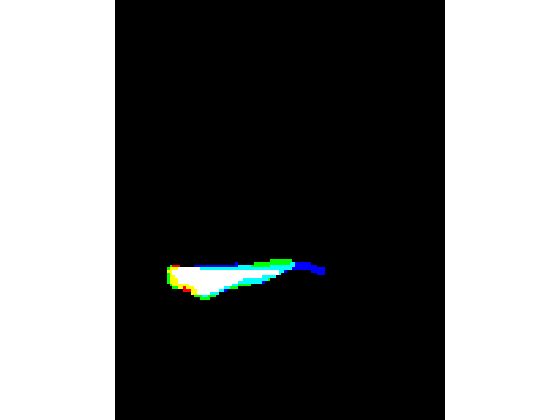

red = imread(path_red);
size(red)

Hmm, red is not a stack -- it only has two dimensions: 512 X 512. 

What did we do wrong? Turns out that **imread **only reads one plane at a time. The default function call simply returns the first plane. To indicate which plane you want to read, you need a second input, as follows:

red2 = imread(path_red, 2);

- this reads the second plane in the stack

So, how do you figure out how many planes are in the stack? You need to read the metadata...

## Read in metadata

Read in the metadata to find out the number of planes in the stack

meta_red = imfinfo(path_red)
meta_blue = imfinfo(path_blue);

#### Plane count

For image stacks, the number of elements in the metadata structure arrays is equal to the number of planes in the volume. So…

numel(meta_red)
numel(meta_blue)

…there are 17 planes in the RED and the BLUE stack. 

#### Structure Array review

Reminder: structure arrays need to be indexed to access information from a given plane

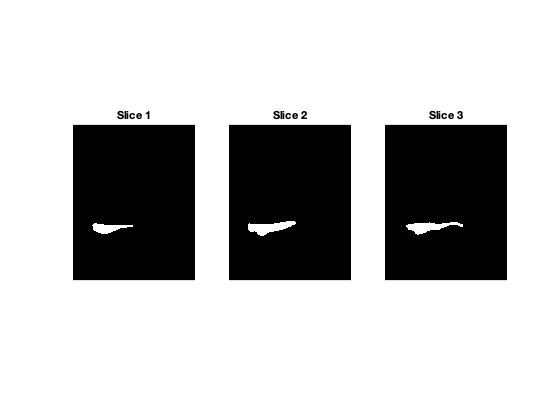

meta_red(5)

- this returns the metadata for the fifth plane

- Notice that the width and the height are the same: the image planes are square

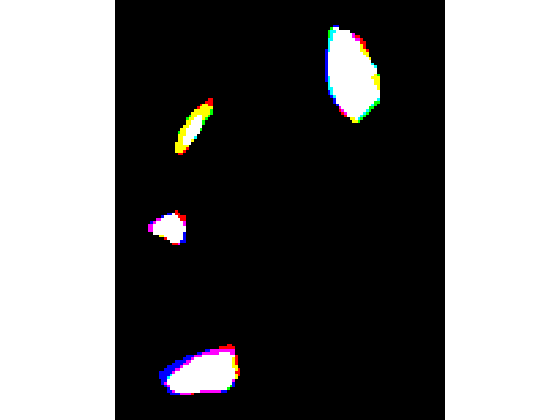

meta_red(5).Width

- This syntax returns the information from the field "width" in the fifth plane from the RED stack metadata

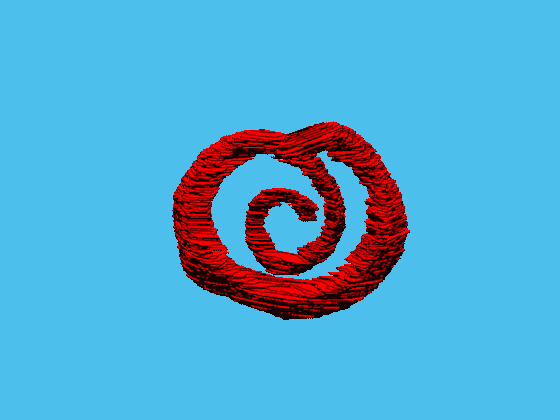

h =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.4900
               Renderer: 'Isosurface'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [0.3000 0.7500 0.9300]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1


meta_blue(5).Width
meta_blue(5).Height

- Notice that the image planes in the BLUE stack has the same dimensions as in the RED stack

meta_blue.Height

RP = 1×3 table
    Volume             Centroid             BoundingBox 
    ______    __________________________    ____________

    96650     59.298    77.787    49.379    [1×6 double]


- This syntax returns the "Height" from all of the planes in the BLUE stack, which necessarily have to be the same. All planes from an image stack have the same width and height. In this example, the BLUE and the RED stacks have the same dimensions

#### Colormaps

The metadata from stacks often include a colormap for each channel. In this example, this specific metadata is saved in the Colormap field

meta_red(1).Colormap
meta_blue(1).Colormap

- Since these are just shades of red and blue, respectively, there are only color values in the first or last column, respectively. 

# IMAGE STACK READ

Now that we have reviewed the metadata, we are ready to load an image stack (hopefully)

## PREALLOCATION

Remember, preallocation is a critical step to save memory. If you don't preallocate, you run the risk of running out of memory for large datasets. This is especially true for image volumes, which tend to be very large arrays. To preallocate, simply create a variable filled with zeros that has the same dimensions as the image stack you are interested in loading. The function **zeros** does exactly that. From the metadata, we know the height and width of each image slice and we know the number of slices. In this example, both the red and blue image stacks have the same number of slices

% Find the number of slices
num_slices = numel(meta_red) % number of slices in the stack.

% Preallocate RED and BLUE
RED = zeros([meta_red(1).Height  meta_red(1).Width num_slices]);
BLUE = zeros([meta_blue(1).Height  meta_blue(1).Width num_slices]);

% DISPLAY stack dimensions in the Command window
fprintf('RED stack: %d x %d X %d\n', size(RED,1), size(RED,2), size(RED,3))
fprintf('BLUE stack: %d x %d X %d\n', size(BLUE,1), size(BLUE,2), size(BLUE,3))

red_la = 1×2 logical array
   0   1


path_red = '/Users/ernesto/MATLAB-Drive/ANAT6205/UNIT 2/data/taste_bud_red.tif'

path_blue = '/Users/ernesto/MATLAB-Drive/ANAT6205/UNIT 2/data/taste_bud_blue.tif'

RED and BLUE are 3D arrays of zeros with the dimensions 512 X 512 X17

## Opening tif image stacks require a for loop.

NOTE: this method only works for **tif** image stacks.

Remember, RED and BLUE have same number of slices. The following FOR LOOP reads the image stack one slice at a time. The stacks the image data. Note that the FOR LOOP loops for the number of slices in the stack. During each loop, one image slice is read into the corresponding plane of the RED and BLUE stacks. 

% read in each slice one at time and load into RED and BLUE
for n=1:num_slices
    RED(:,:,n) = imread(path_red, n);

ans =    512   512


    BLUE(:,:,n) = imread(path_blue, n);
end

% DISPLAY pixel values in command window
fprintf('RED stack: MAX-%d, MIN-%d, RANGE-%d\n', max(RED(:)), min(RED(:)), range(RED(:)))
fprintf('BLUE stack: MAX-%d, MIN-%d, RANGE-%d\n', max(BLUE(:)), min(BLUE(:)), range(BLUE(:)))

- OK, we've got stacks!

- With pixel values above zero

## Display the RED and BLUE image stacks 

Let's start by grabbing the middle slice from each stack and displaying

figure;

meta_red = 17×1 struct array with fields:
    Filename
    FileModDate
    FileSize
    Format
    FormatVersion
    Width
    Height
    BitDepth
    ColorType
    FormatSignature
    ByteOrder
    NewSubFileType
    BitsPerSample
    Compression
    PhotometricInterpretation
    StripOffsets
    SamplesPerPixel
    RowsPerStrip
    StripByteCounts
    XResolution
    YResolution
    ResolutionUnit
    Colormap
    PlanarConfiguration
    TileWidth
    TileLength
    TileOffsets
    TileByteCounts
    Orientation
    FillOrder
    GrayResponseUnit
    MaxSampleValue
    MinSampleValue
    Thresholding
    Offset
    ImageDescription


red = RED(:,:,10);
blue = BLUE(:,:,10);

subplot(1,2,1); imshow(red);
subplot(1,2,2); imshow(blue);

ans = 17

- Hmm, stacks loaded, but why are the slices so overexposed?

- Hint: what are the bit depths of the image stacks? (check max pixel value)

- What class are RED and BLUE? (Check Workspace) What should they be? (uint8)

## Recast stacks

Stacks have the wrong numeric class: they are double, they should be an 8-bit integer class. So, simply recast them as integers:

RED = uint8(RED); % convert to an 8-bit unsigned integer

ans = 17

BLUE = uint8(BLUE); % convert to an 8-bit unsigned integer

red = RED(:,:,10);
blue = BLUE(:,:,10);

Display the results

figure;

ans = struct with fields:
                     Filename: '/Users/ernesto/MATLAB-Drive/ANAT6205/UNIT 2/data/taste_bud_red.tif'
                  FileModDate: '19-Jul-2016 20:47:55'
                     FileSize: 4461049
                       Format: 'tif'
                FormatVersion: []
                        Width: 512
                       Height: 512
                     BitDepth: 8
                    ColorType: 'indexed'
              FormatSignature: [77 77 0 42]
                    ByteOrder: 'big-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'RGB Palette'
                 StripOffsets: 1817
              SamplesPerPixel: 1
                 RowsPerStrip: 512
              StripByteCounts: 262144
                  XResolution: 4.9842
                  YResolution: 4.9842
               ResolutionUnit: 'None'
                     Colormap: [256×3 double]
          PlanarCon

tiledlayout(1,2,"TileSpacing","compact")
nexttile; imshow(red);
nexttile; imshow(blue);

ans = 512

- That's better. 

Our overexposure problem originated in the preallocation step. We should have preallocated the stacks of zeros to an unsigned 8-bit integer class (uint8), instead of double, as follows:

- notice the addition of the 'uint8' at the end there

## Colormaps included

As we previously mentioned, the metadata included colormaps for each stack. We can apply these colormaps to the images as follows:

figure;

ans = 512

tiledlayout(1,2,"TileSpacing","compact")

ans = 512

nexttile; imshow(red,'Colormap',meta_red(10).Colormap);
title('red slice')


ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

ans = 512

nexttile; imshow(blue,'Colormap',meta_blue(10).Colormap);
title('blue slice')

- Now in color, but it actually makes the details harder to see

- Gray is better (or maybe parula)

## Explore the volumes

Using the Volume Viewer app.

- Convert the rendering to an isosurface and set the isovalue lower (move slider  far to the left).

volumeViewer(RED);

- Notice how flat this dataset is. There are relatively few number of slices compared to the number of rows and columns

Repeat with the blue volume, but using the function **volshow.**

☑️ Enter the syntax here:

volshow(BLUE)

num_slices = 17

## RED STACK Projection

Projections simplify viewing an image stack. Recall that a projection is simply a flattened 2D view of a 3D stack. We can easily create a max projection using the function **max**. We will display this projection using **imshow** and the parula colormap. We will also plot its histogram

r_projection = max((RED),[],3); %max of each column along the 3rd dimension

figure;
subplot (1,2,1)
imshow(r_projection, parula(256)); % notice the additional input of Colormap to imshow

RED stack: 512 x 512 X 17


title ('RED max projection');

BLUE stack: 512 x 512 X 17


subplot (1,2,2)
imhist(r_projection);
axis square
title('histogram of RED projection')
impixelinfo

## BLUE STACK PROJECTION

Try it yourself. Create a new matrix called *b_projection* that contains the max projection from the ***BLUE*** stack

☑️ Fill in the empty bracket below:

b_projection = max(BLUE,[],3); %max of each column along the 3rd dimension

Display the projection and a histogram

figure;

RED stack: MAX-242, MIN-0, RANGE-242


subplot (1,2,1)

BLUE stack: MAX-255, MIN-0, RANGE-255


imshow(b_projection, parula(256)); % 
title ('BLUE max projection');
subplot (1,2,2)
imhist(b_projection);
title('histogram of projection')
impixelinfo

# Segmentation

Fortunately, we can use the same segmentation strategies that we used for 2D images.

In this example, we already have the channels separated, which simplifies things. 

## Enhancement

First, we need to enhance the image. 

Let's start by inspecting the histogram

figure;
subplot(1,2,1); imhist(RED); title('RED Stack')
subplot(1,2,2); imhist(BLUE); title('BLUE Stack')

- These are histograms of the entire stacks 

- And, yep, they are pretty dim and could use some enhancement

## Normalize

The function **mat2gray** can be used on image stacks as well to divide all pixel intensities by the max pixel intensity found in the stack

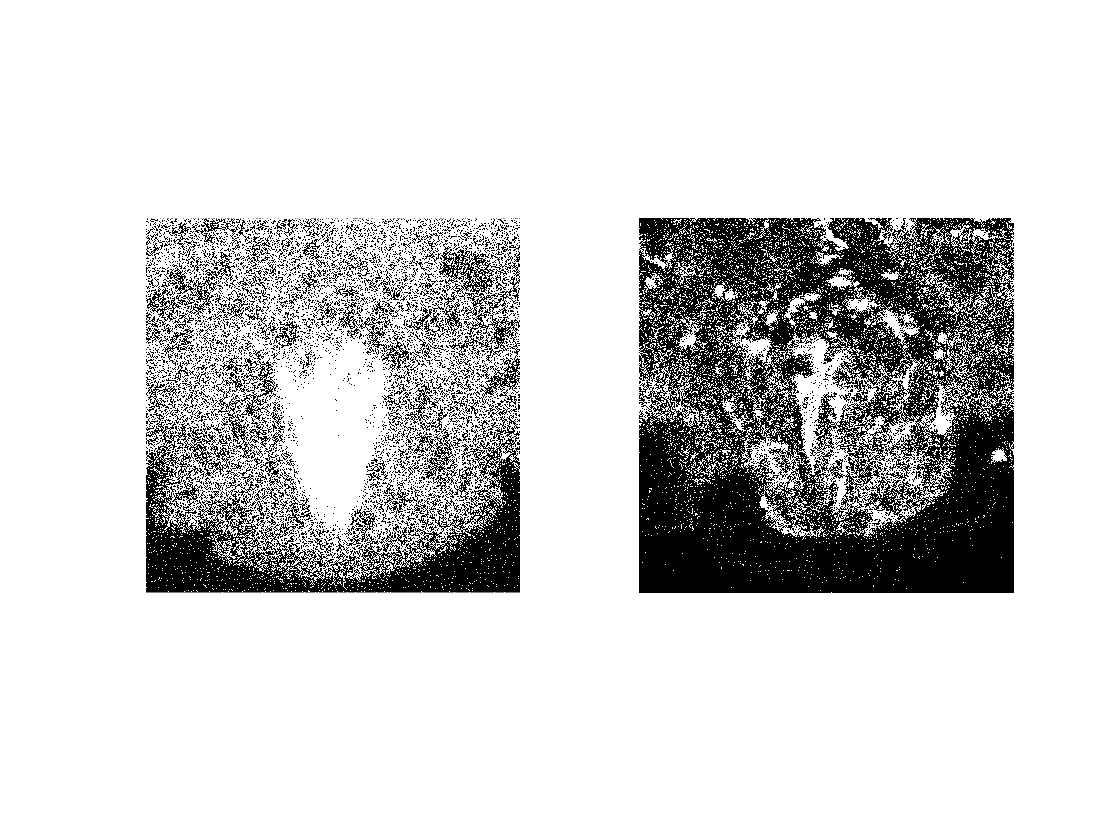

REDe = mat2gray(RED);

☑️ Normalize the BLUE stack by overwriting the empty brackets here (don't forget your semi-colon):

BLUEe = mat2gray(BLUE);

## Enhance 

There seems to be some background noise, so let's use a median filter to clean some of that up. Note the use of the function **medfilt3** here (as compared to medfilt2 for images)

REDe = medfilt3(REDe);

☑️ Perform the same operation on the BLUEe stack here:

BLUEe = medfilt3(BLUEe);

## Inspect Volume

So, how did we do?

figure('Name','Red'); volshow(RED);
figure("Name",'Enhanced'); volshow(REDe)

- Great, a lot of the background noise appears to be cleaned up, let's keep moving

## Threshold

You can use **imbinarize** to threshold the entire stack, as follows

RBW = imbinarize(REDe);

☑️Fill in the brackets to binarize the BLUE channel

BBW = imbinarize(BLUEe);

## Inspect Mask

Using the function volshow

volshow(RBW,'Renderer','Isosurface')

- looks good. Just some noise

Display the blue binary channel, BBW, in the same way

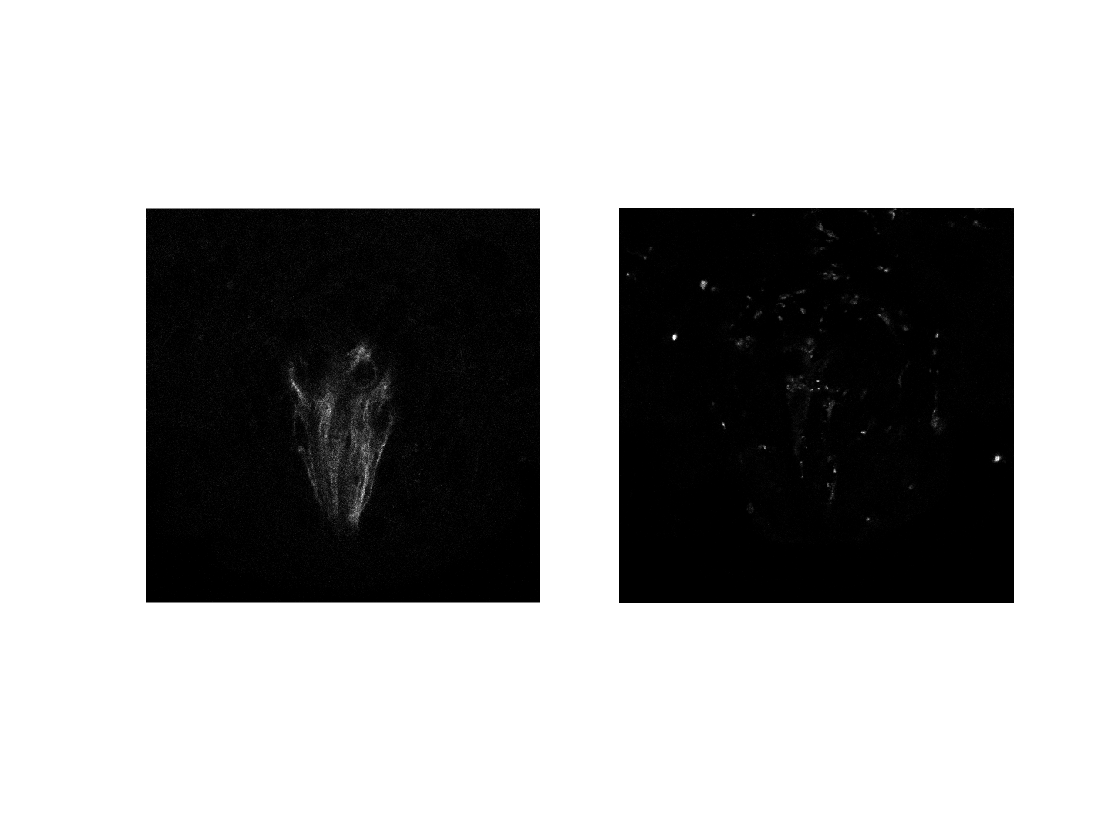

volshow(BBW,'Renderer','Isosurface')

- So, it all looks pretty good

- But, is it?

- What we really need is a way to inspect the mask on the original data, kind of like **imshowpair** but in 3D

## IMSTACK

I wrote a toolbox **imstack** to easily explore and threshold image stacks. It can open confocal stacks (using **bioformats**), DICOM stacks, etc. Both **imstack **and **bioformats** are complicated functions that actually are made up of a entire folder of functions. 

To get these functions to work, you need to add their folders to the MATLAB search path, as follows:

- Click on 'Set Path' in the Home tab  

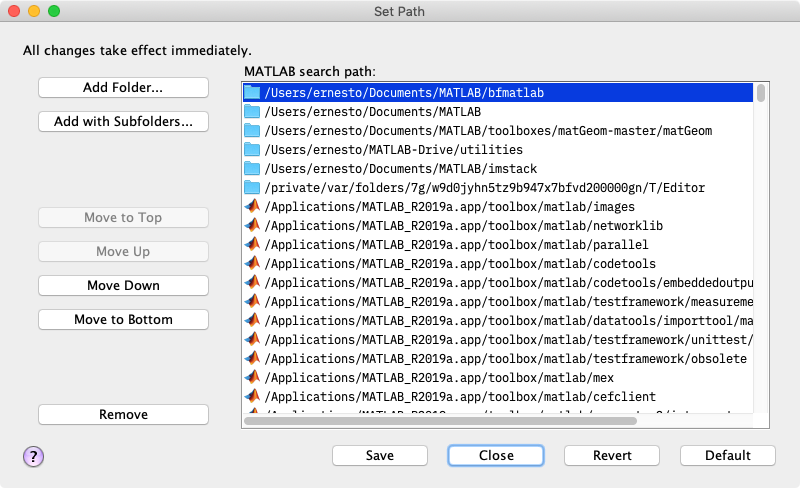

- Click on the 'Add Folder...' button

- Navigate to the "MATLAB Drive : ANAT 6205 : Functions" folder

- Select both 'imstack' and 'bfmatlab'

- Click on 'Save' and 'Close'

## Compare Stack and Mask

In this example, we will compare the original red stack to the mask we generated

imstack(RED, [], RBW)

## Compare Stack and Enhanced Stack

You can even compare the original stack to its enhanced version

imstack(RED, [], REDe)

imstack(BLUEe, [],BBW)

- hmm, seems like we are missing some of the data

## Adjust Blue Thresholding

We seemed to be missing some of the signal in the BLUE stack. A simple way to solve this problem is to lower the threshold value. The function **graythresh** also accepts an image stack. We will lower the resultant threshold value using a factor of 0.25. 

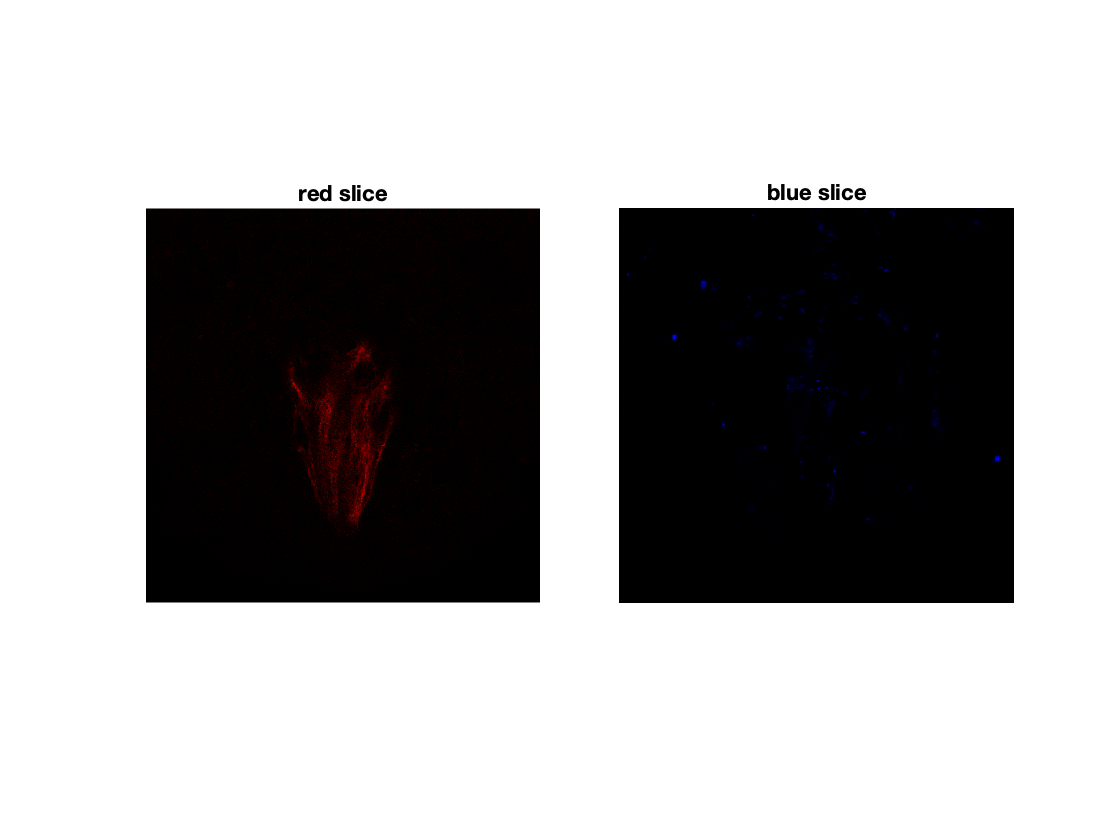

lvl = graythresh(BLUEe);
factor = 0.25; % starts at 0.5
BBW = imbinarize(BLUEe,lvl*factor); % adjust factor
imstack(BLUE, [], BBW)

## Morpological Operations

Use a morphological open to clean up small noise in a mask. The function **bwareaopen** is the easiest way to tackle this (it accepts a 3D mask)

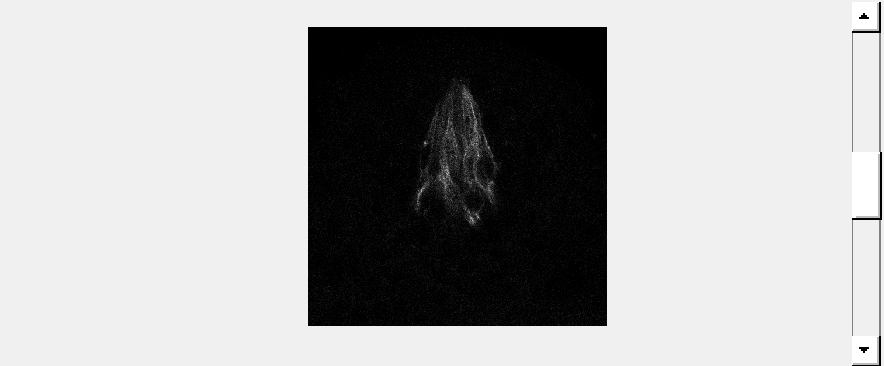

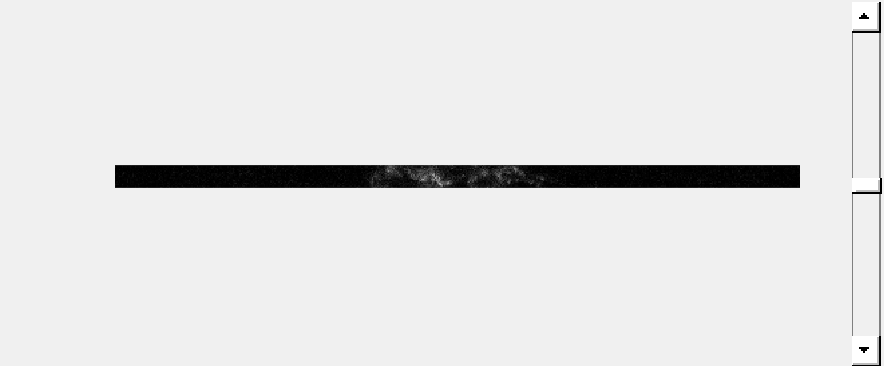

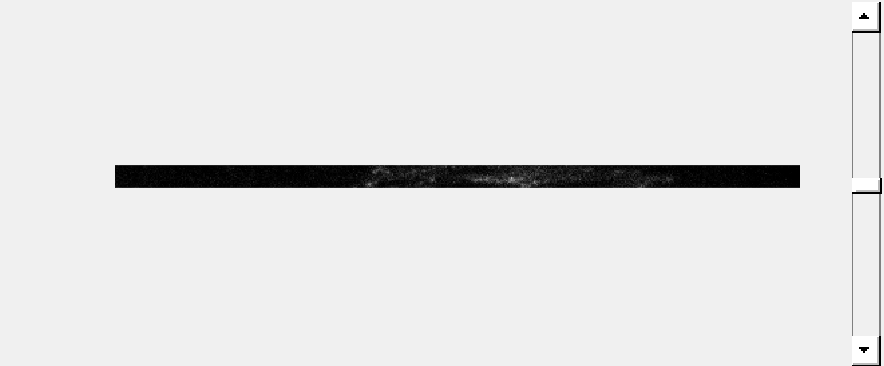

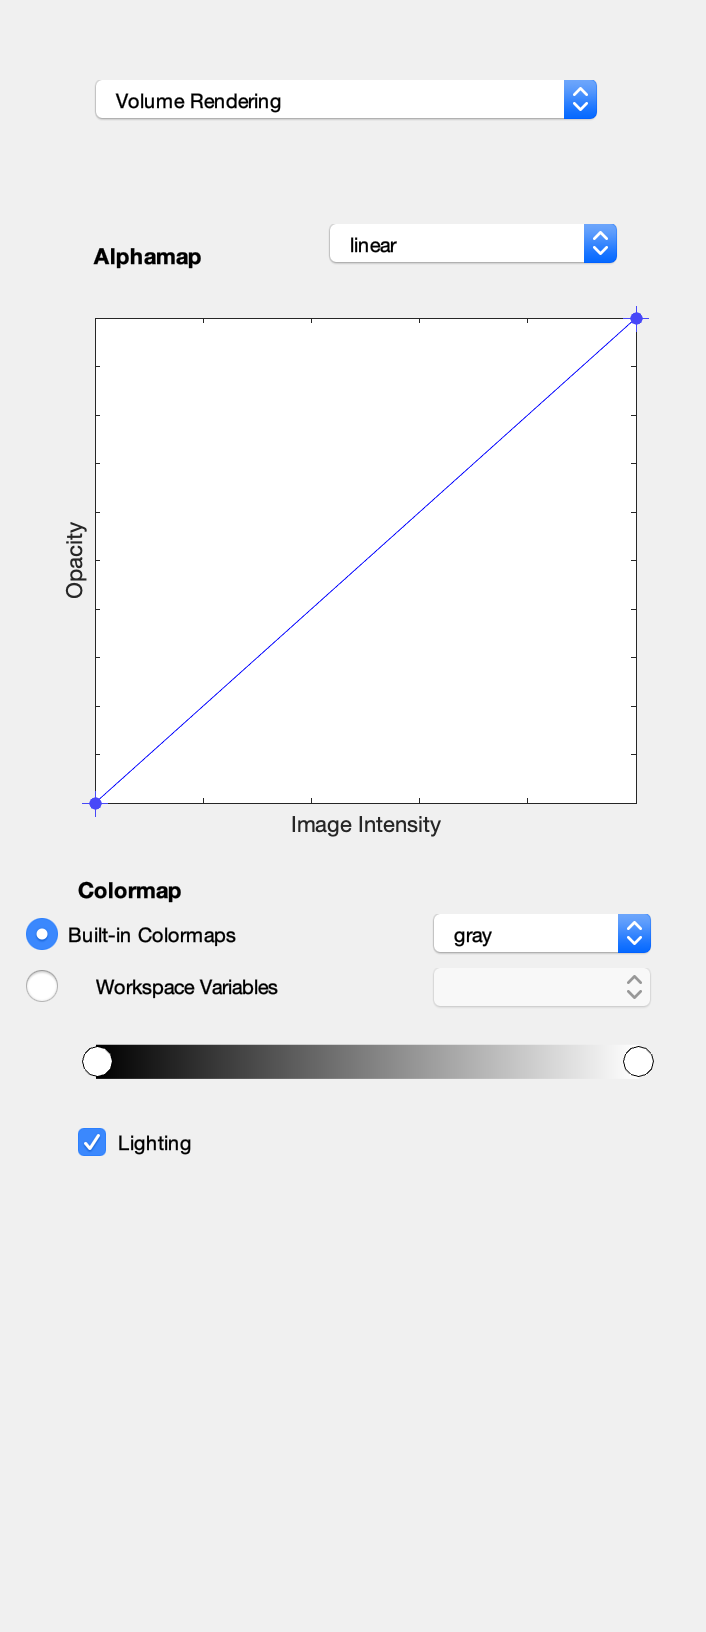

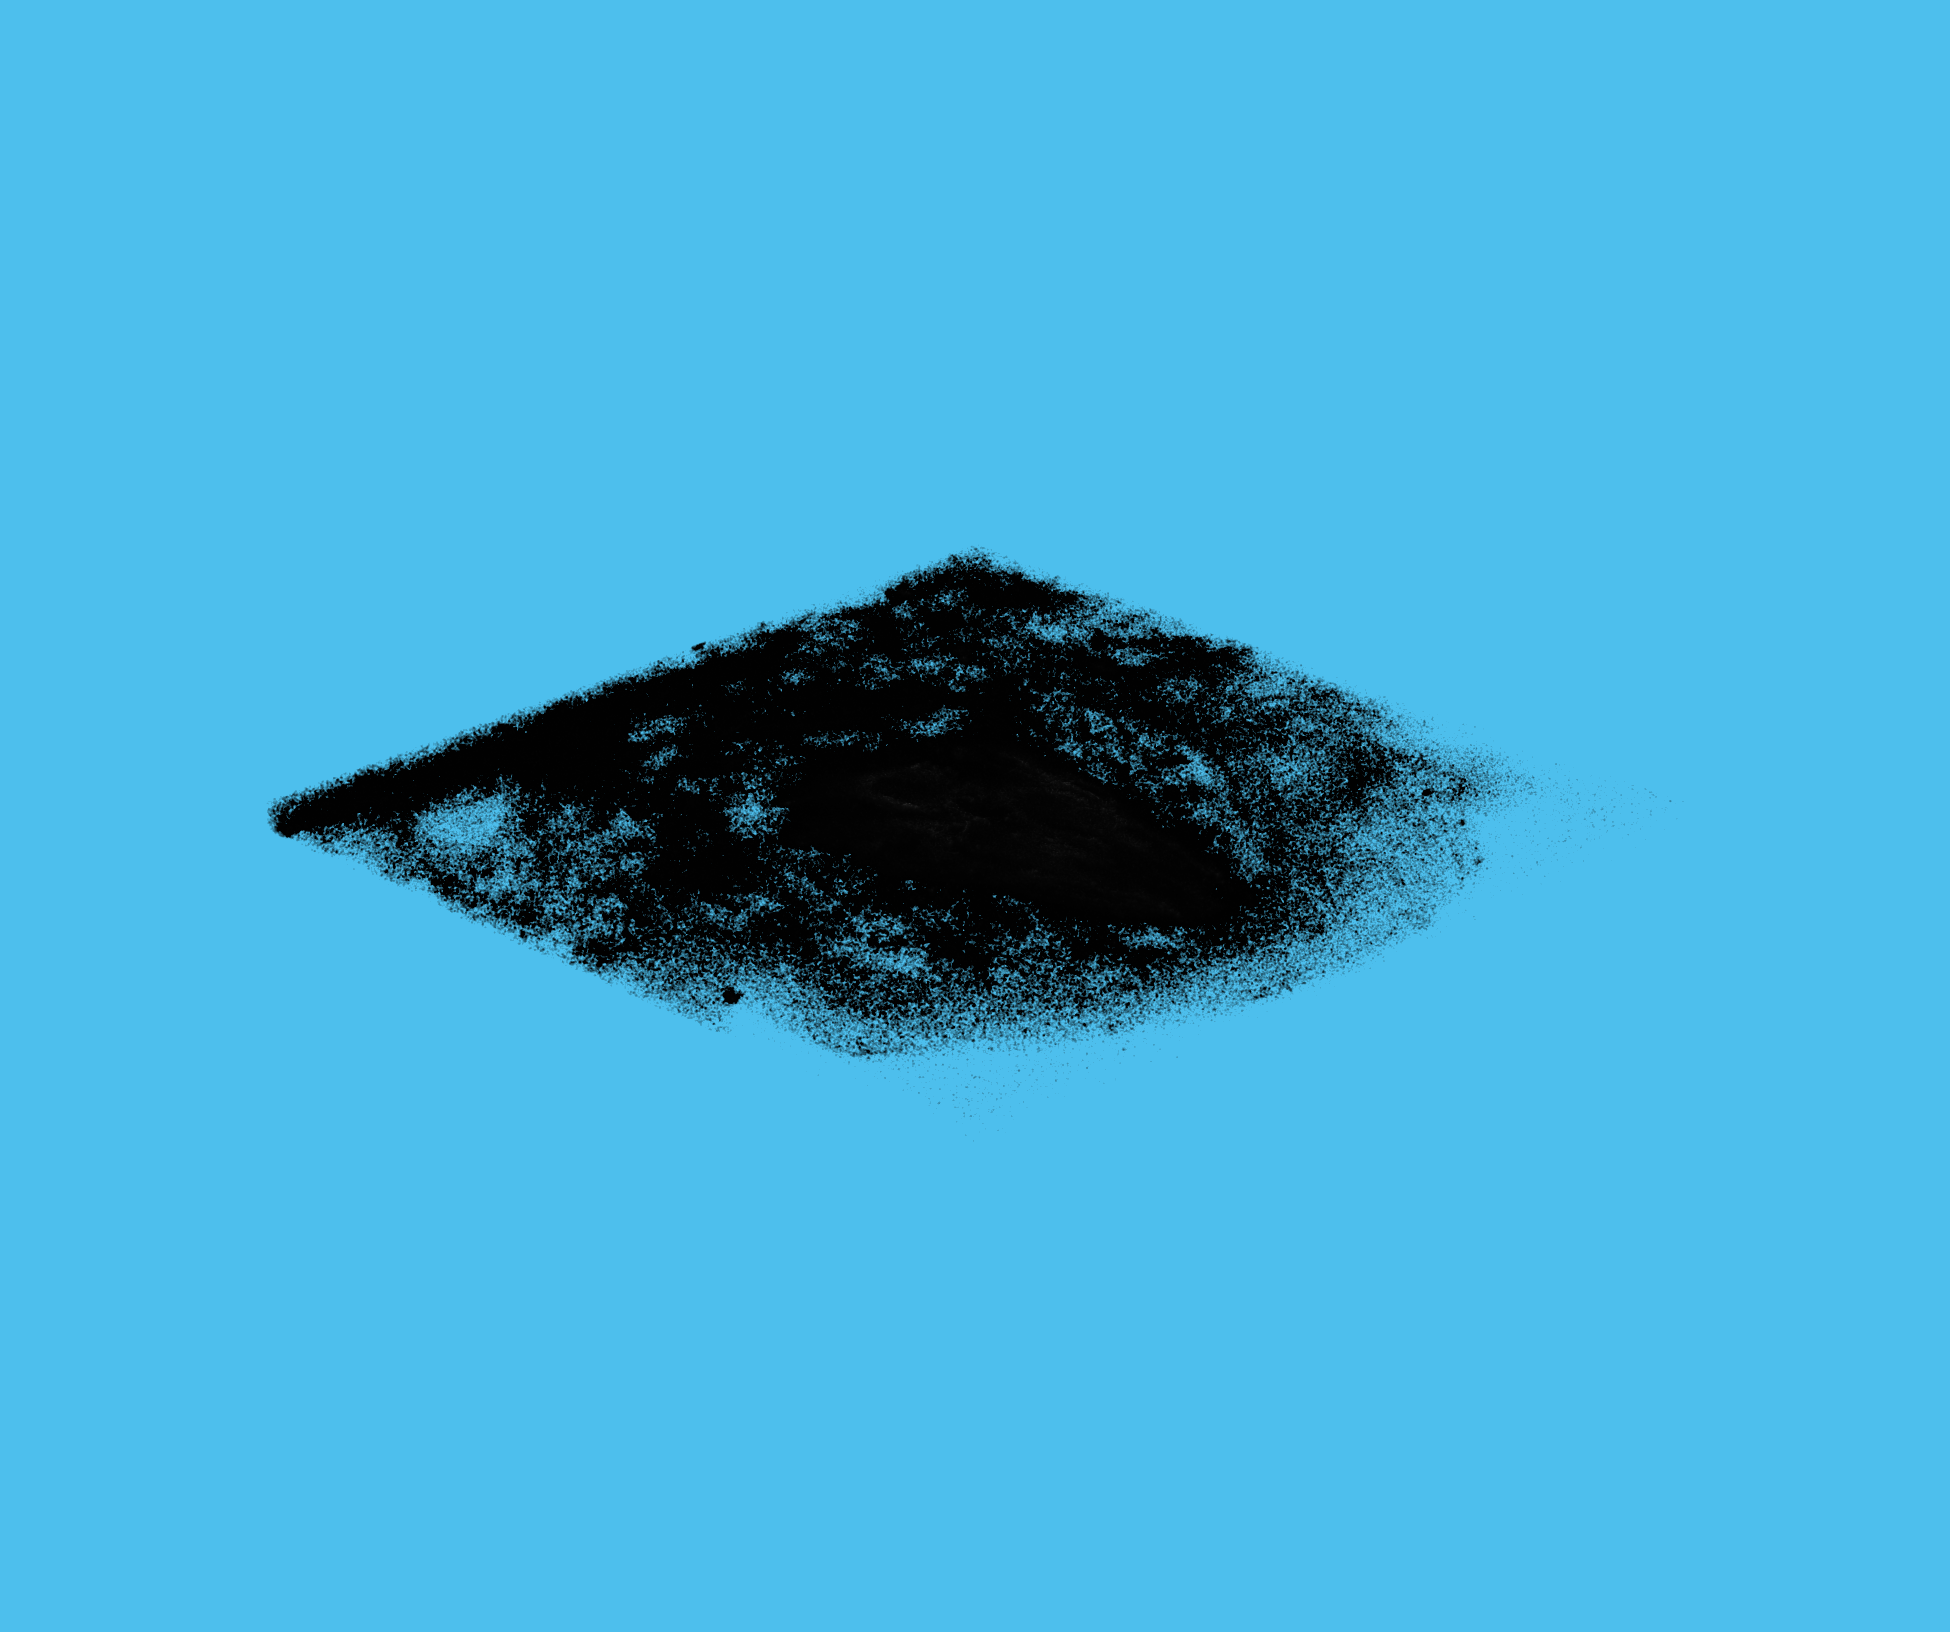

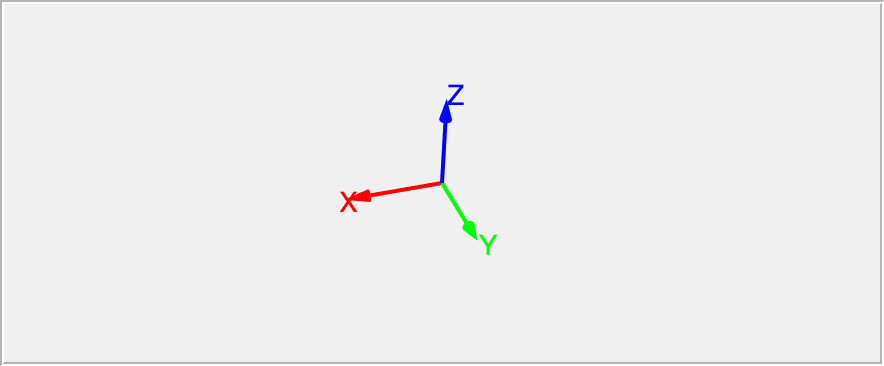

RBW = bwareaopen(RBW, 50);

BBW = bwareaopen(BBW, 25);
imstack(RBW,[],BBW)

## Logical Operations

Find the synaptic contact points using a LOGICAL AND

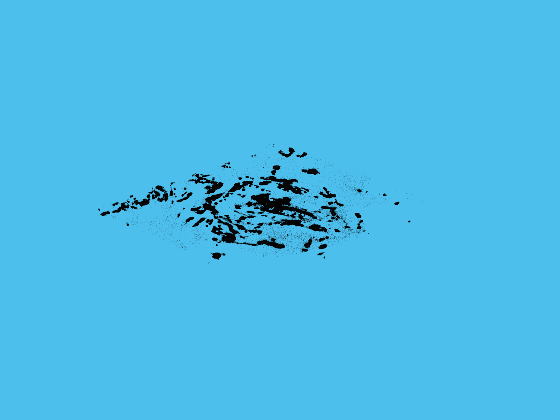

ans =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.5000
               Renderer: 'VolumeRendering'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [0.3000 0.7500 0.9300]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1


OVERLAP = RBW&BBW;

imstack(RBW,[],OVERLAP)

## Region Properties

Notice that there is a 3D version of regionprops. Works almost the same, but in 3D

RP = regionprops3(OVERLAP)

- Instead of AREA, you get VOLUME

# Come with me to the fourth dimension and beyond

## A word about dimensions

An array can have as many dimensions as you want. It's just really hard to visualize any dimensions beyond the 3RD dimension.  When you are dealing with 3D Datasets and you want to add a color channel, you need to dabble in the fourth dimension.

When dealing with more than three dimensions, the standard order for dimensions in MATLAB is as follows:

- 1st Dimension - rows

- 2nd Dimension - cols

- 3rd Dimension - channel

- 4th Dimension - plane (slice)

- 5th Dimension - time (we'll get to this later)

4D and 5D arrays are really all about packaging. Just think of them as stacks of images, sorted by channel, z-slice, and (sometimes) time

## Reshape RED into a 4D array 

We will use the function **reshape **to change a 3D array into a 4D array. Simply input the array that you want to resize, then input the size of the dimensions. In this case, we are going to reshape *REDe* so that it has the same number of rows and columns, has a singleton dimension (size of 1) in the 3rd dimension, and has the same number of planes (17), but in the fourth dimension. So basically, we are moving the 3rd dimension to the fourth dimension

RGB4 = reshape(REDe, size(RED,1), size(RED,2),1,size(RED,3)); % REDe, 512, 512, 1, 17
RGB4 = im2uint8(RGB4); % typecase back to an integer class
size(RGB4)

- yep, 4D

## Add channels

Lets add more channels to our 4Dstack. Green will be all zeros. Notice that we can index 3D arrays into our 4D array, as long as we index properly.

GREEN = zeros(size(RED),'uint8'); % a 3D array of zeros
RGB4(:,:,2,:) = GREEN; % index is all rows, all columns, channel 2, all planes
RGB4(:,:,3,:) = BLUEe; % index is all rows, all columns, channel 3, all planes

- Ok, looks like it worked. 

Now what?

## Display 4D stack as a montage

Display all slices in color. The function **montage** accepts 4D arrays and creates a montage of RGB images

figure;
montage(RGB4)

## imstack

**imstack** can also handle 4D slices and you can scrub through each plane to see them in RGB color. Right-click on an image and select auto-contrast to see the image better

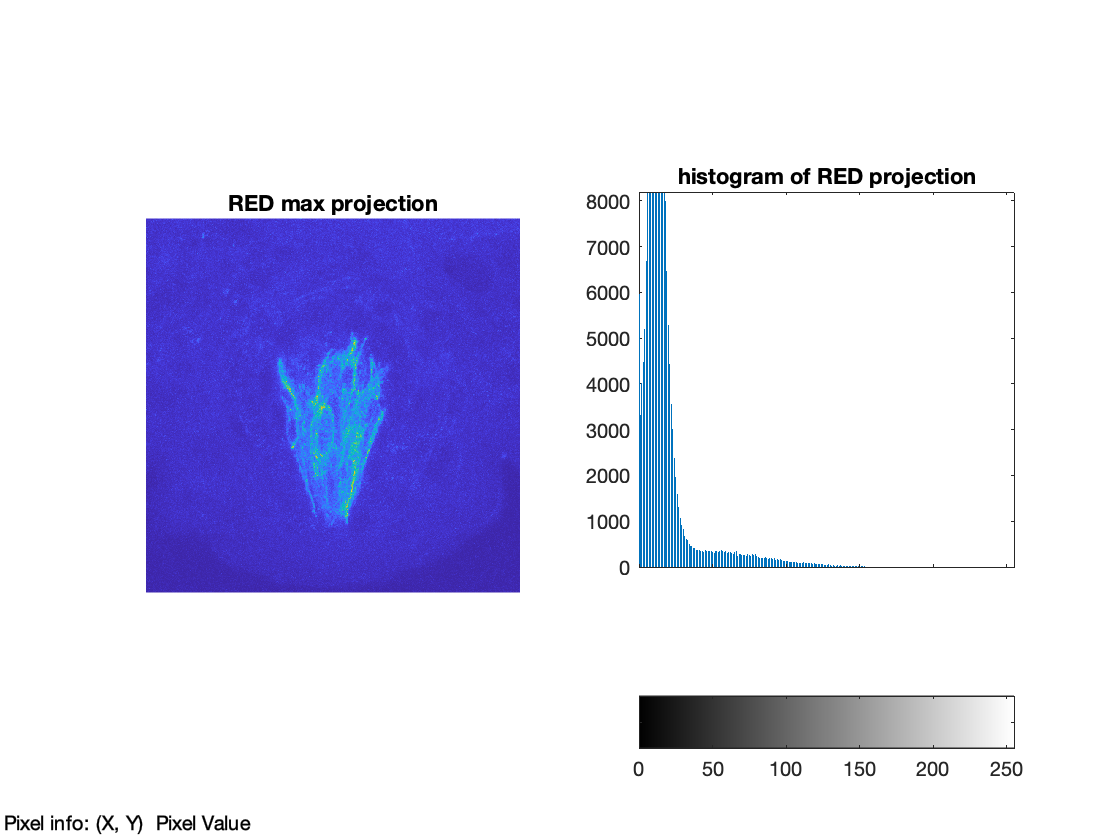

imstack(RGB4)

## 4D Masks

We can perform the same operations for the masks. First, we will reshape one of the masks into a 4D logical array. Then we will index into this 4D array the other two 3D logical arrays

BW4 = reshape(RBW,size(RBW,1),size(RBW,2),1,size(RBW,3)); % reshape the RED mask into a 4D array and assign to BW4
BW4(:,:,2,:) = false(size(RBW)); % index in a 3D array of falses
BW4(:,:,3,:) = BBW; % index in the blue channel: all rows, all columns, third channel, all planes

montage(im2uint8(BW4)) % typecast the logical array to a single because montage can't display logical arrays

## imstack 

Imstack can handle them both

imstack(RGB4,[],BW4)

## Publication

This sample script was modified from data analysis published in Development by the Barlow LAB Rocky Mountain Taste and Smell Center

web('http://www.ncbi.nlm.nih.gov/pubmed/24993944','-browser')

# Local Functions

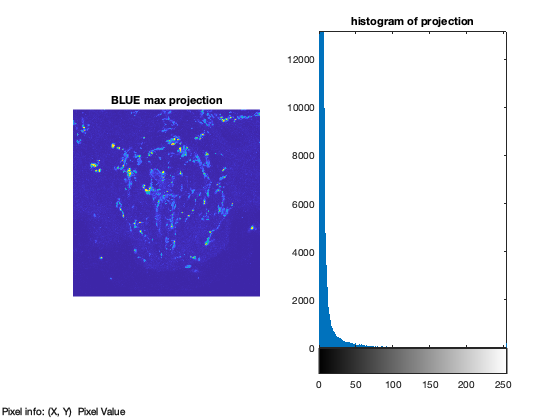

function slice_animation
clear
close all

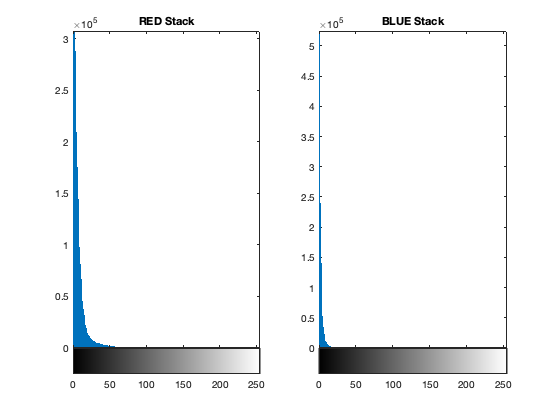

clc
figure('Visible','on');

s = 10; % size of cube
x=[0 1 1 0 0 0;1 1 0 0 1 1;1 1 0 0 1 1;0 1 1 0 0 0]*s*2;
y=[0 0 1 1 0 0;0 1 1 0 0 0;0 1 1 0 1 1;0 0 1 1 1 1]*s*2;
z=[0 0 0 0 0 1;0 0 0 0 0 1;1 1 1 1 0 1;1 1 1 1 0 1]*s;

for i=1:6 % plot each face of cube in 3D
    ch=patch(x(:,i),y(:,i),z(:,i),'k','facealpha',0.1);

    set(ch,'edgecolor','w')
end

% set viewing angle and shape
view([-27 40])
axis equal
set(gca, "FontSize", 14)
xlabel('cols',"FontSize",16,"FontWeight","bold")
ylabel('rows',"FontSize",16,"FontWeight","bold")
zlabel('slices',"FontSize",16,"FontWeight","bold")

title('image stack - DS')


view([-52.60 38.40])


s = 10;
x=[0 1 1 0 0 0;1 1 0 0 1 1;1 1 0 0 1 1;0 1 1 0 0 0]*s*2;
y=[0 0 1 1 0 0;0 1 1 0 0 0;0 1 1 0 1 1;0 0 1 1 1 1]*s*2;

ans =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.5000
               Renderer: 'VolumeRendering'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [0.3000 0.7500 0.9300]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1


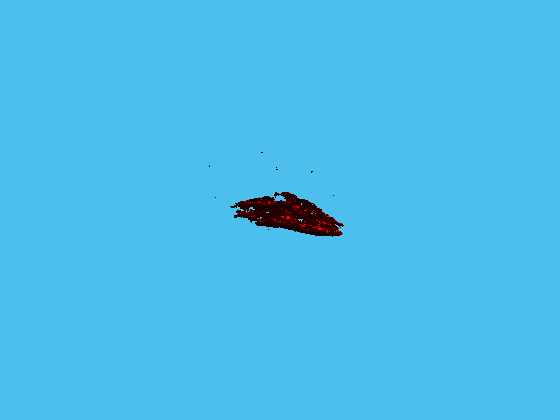

ans =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.4900
               Renderer: 'Isosurface'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [0.3000 0.7500 0.9300]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1



ch = [];

for n = 1:s
    
    delete(ch)
    z=[0 0 0 0 0 1;0 0 0 0 0 1;1 1 1 1 0 1;1 1 1 1 0 1]*1+n;
    
    for i=1:6
        ch(i)=patch(x(:,i),y(:,i),z(:,i),'y','facealpha',.5);        
    end
    

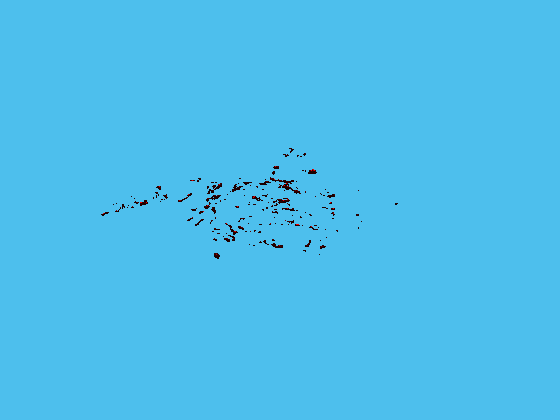

ans =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.4900
               Renderer: 'Isosurface'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [0.3000 0.7500 0.9300]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1


    set(ch,'edgecolor','w')
    view([-27 40])
    axis equal
    

Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


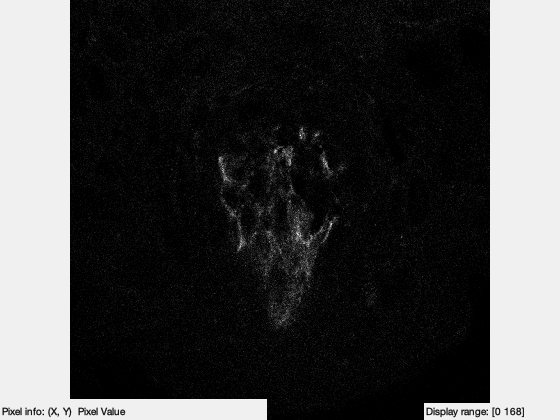

ans =   Figure (imstack_fig) with properties:

      Number: 6
        Name: 'IMSTACK | 1 | 17 | RED - '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


ans =   Figure (imstack_fig) with properties:

      Number: 6
        Name: 'IMSTACK | 1 | 17 | RED - '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


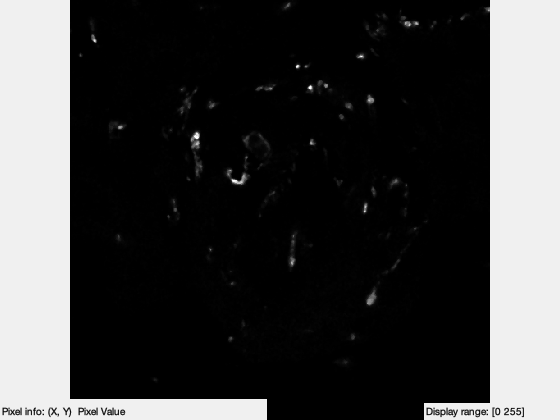

ans =   Figure (imstack_fig) with properties:

      Number: 4
        Name: 'IMSTACK | 1 | 17 | BLUEe - '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


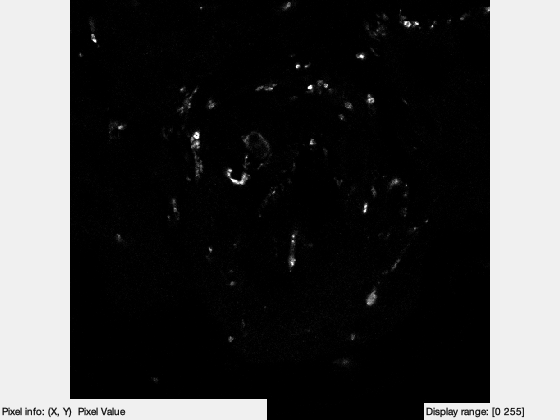

ans =   Figure (imstack_fig) with properties:

      Number: 4
        Name: 'IMSTACK | 1 | 17 | BLUE - '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


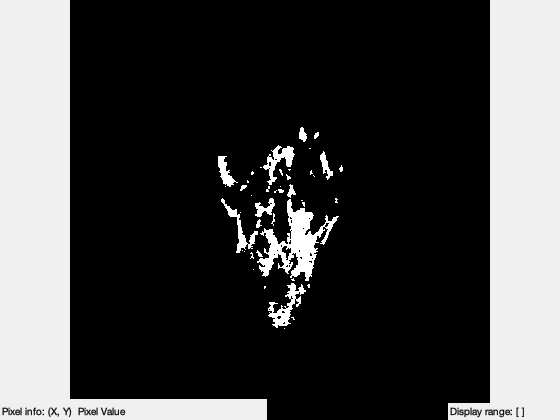

ans =   Figure (imstack_fig) with properties:

      Number: 4
        Name: 'IMSTACK | 1 | 17 | RBW - '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


ans =   Figure (imstack_fig) with properties:

      Number: 4
        Name: 'IMSTACK | 1 | 17 | RBW - '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


RP = 48×3 table
    Volume             Centroid             BoundingBox 
    ______    __________________________    ____________

     9029     239.95    246.41    8.3221    [1×6 double]
        2      232.5     204.5       1.5    [1×6 double]
     1151     271.79    304.65    2.9618    [1×6 double]
       17     269.06    221.88    2.1176    [1×6 double]
      564     285.87    305.49    4.0266    [1×6 double]
        3     311.67    189.67    1.3333    [1×6 double]
       18      220.5    216.28    4.3333    [1×6 double]
       33      270.7    206.55    3.3636    [1×6 double]
      112     273.86    186.27    6.7946    [1×6 double]
       33      323.7    220.27    3.3636    [1×6 double]
        5      215.6     220.4       3.8    [1×6 double]
       14     267.21    180.21    4.1429    [1×6 double]
       15        296    174.67    3.9333    [1×6 double]
       28     298.75    21

ans =    512   512     1    17


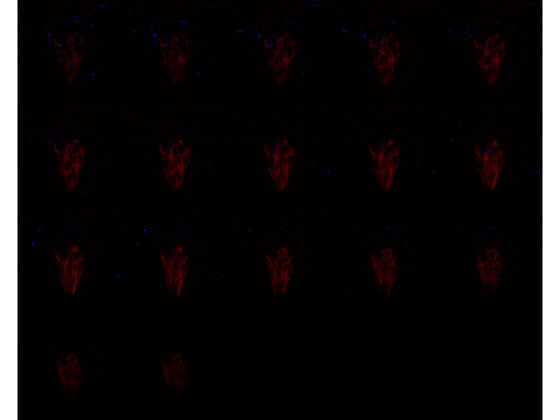

Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


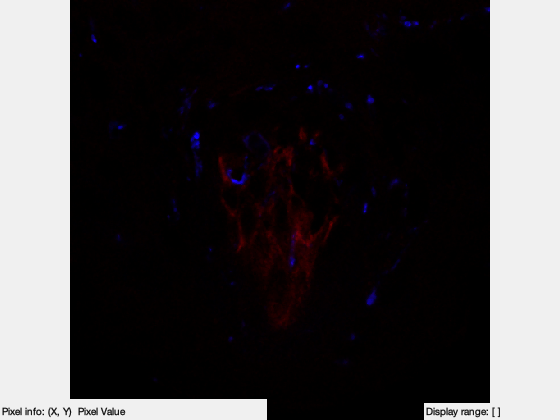

ans =   Figure (imstack_fig) with properties:

      Number: 6
        Name: 'IMSTACK | 1 | 17 | RGB4 -  (all) '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


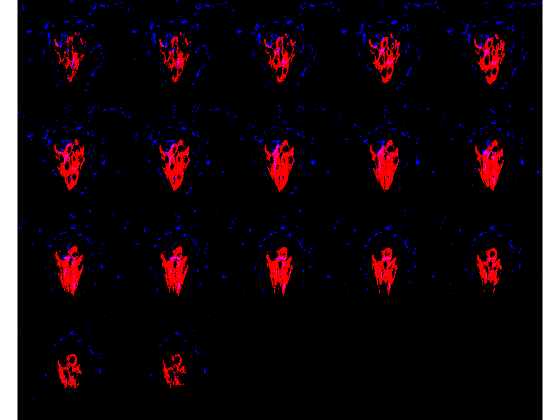

Script Path: /Users/ernesto/Documents/MATLAB/imstack/scripts/gaillard2020


ans =   Figure (imstack_fig) with properties:

      Number: 6
        Name: 'IMSTACK | 1 | 17 | RGB4 -  (all) '
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


    drawnow
    title(sprintf('image slice - STACK(:,:,%d)',n),"FontSize",18)
    pause(1)
    
end
end